# Communication systems laboratory Lab3

B12901052 高瑞謙

## [Part1]

FFT_size = 64;
cp_size = 16;
fs = 20e6;
sc_space = fs/FFT_size;
%% 802.11a/g subcarrier allocation
active_sc  = [-26:-1 1:26];           % 52 active subcarriers
pilot_sc = [-21 -7 7 21];           % 4 pilot tones
data_sc  = setdiff(active_sc, pilot_sc); % 48 data tones

### (1)

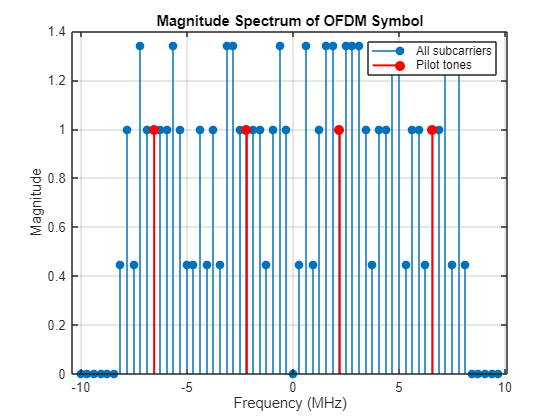

%% 1. Generate pilot symbols (BPSK)
pilot_bits = randi([0 1], length(pilot_sc), 1);
pilot_sym = 2*pilot_bits - 1;       

%% 2. Generate data symbols (16-QAM)
% 16-QAM => 4 bits per symbol
data_bits = randi([0 1], length(data_sc)*4, 1);
data_sym = qammod(data_bits, 16, 'InputType', 'bit', 'UnitAveragePower', true);

%% 3. Generate OFDM symbols
Xc = zeros(FFT_size,1);
sc2idx = @(k) k + FFT_size/2 + 1; % map the sc idx to 1-64

% map pilot&data
for i = 1:length(pilot_sc)
    Xc(sc2idx(pilot_sc(i))) = pilot_sym(i);
end
for i = 1:length(data_sc)
    Xc(sc2idx(data_sc(i))) = data_sym(i);
end

f_axis = (-FFT_size/2 : FFT_size/2-1) * sc_space / 1e6;
pilot_idx = sc2idx(pilot_sc);
figure;
stem(f_axis, abs(Xc), 'filled');
hold on;
stem(pilot_sc * sc_space / 1e6, abs(Xc(pilot_idx)), 'r', 'filled', 'LineWidth', 1.5);
grid on;

xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('Magnitude Spectrum of OFDM Symbol');
legend('All subcarriers','Pilot tones');

### (2)


$$\textrm{subcarrier}\;\textrm{spacing}=\frac{\textrm{sampling}\;\textrm{frequency}}{\textrm{FFT}\;\textrm{size}}=\frac{20*{10}^6 }{64}=0\ldotp 3125\textrm{MHz}$$


### (3)

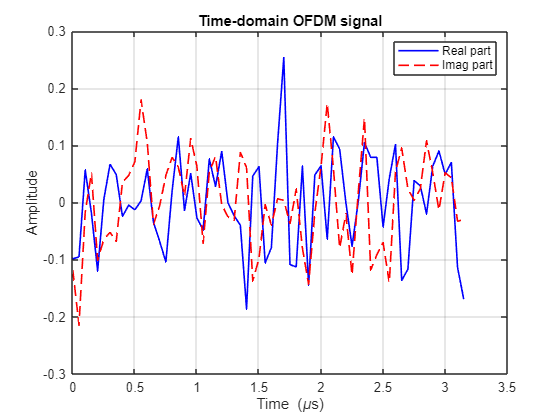

a = ifft(ifftshift(Xc));
t = (0:length(a)-1) / fs * 1e6;  

figure;
plot(t, real(a), 'b', 'LineWidth', 1.2); 
hold on;
plot(t, imag(a), 'r--', 'LineWidth', 1.2);
grid on;

xlabel('Time (\mus)');
ylabel('Amplitude');
title('Time-domain OFDM signal');
legend('Real part', 'Imag part');

### (4)

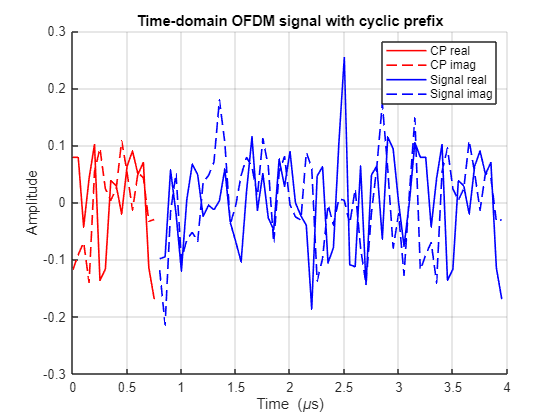

% Add cyclic prefix
b = [a(end-cp_size+1:end); a];  
t = (0:length(b)-1) / fs * 1e6; 
cp_idx  = 1:cp_size;             
sig_idx = cp_size+1:length(b);   

figure;
hold on; grid on;
% CP part
plot(t(cp_idx),  real(b(cp_idx)),  'r',  'LineWidth', 1.2);
plot(t(cp_idx),  imag(b(cp_idx)),  'r--','LineWidth', 1.2);

% signal part
plot(t(sig_idx), real(b(sig_idx)), 'b',  'LineWidth', 1.2);
plot(t(sig_idx), imag(b(sig_idx)), 'b--','LineWidth', 1.2);

xlabel('Time (\mus)');
ylabel('Amplitude');
title('Time-domain OFDM signal with cyclic prefix');
legend('CP real','CP imag','Signal real','Signal imag');

### (5)


$$\textrm{duration}\;\textrm{of}\;\textrm{OFDM}\;\textrm{with}\;\textrm{cp}:t=\frac{1}{\textrm{sampling}\;\textrm{frequecny}}*\textrm{numbers}\;\textrm{of}\;\textrm{samples}=\frac{1}{20*{10}^6 }*\left(64+16\right)=4\mu s$$



$$\textrm{duration}\;\textrm{of}\;\textrm{OFDM}\;\textrm{without}\;\textrm{cp}:t=\frac{1}{\textrm{sampling}\;\textrm{frequecny}}*\textrm{numbers}\;\textrm{of}\;\textrm{samples}=\frac{1}{20*{10}^6 }*\left(64\right)=3\ldotp 2\mu s$$


### (6)

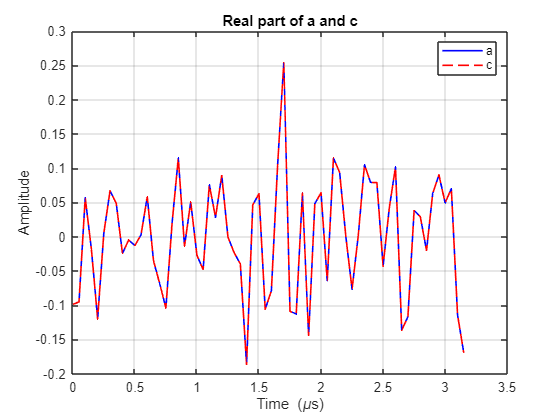

c = b(cp_size+1:end);  
t = (0:length(c)-1) / fs * 1e6;

figure;
plot(t, real(a), 'b', 'LineWidth', 1.2); 
hold on;
plot(t, real(c), 'r--', 'LineWidth', 1.2);
grid on;

xlabel('Time (\mus)');
ylabel('Amplitude');
title('Real part of a and c');
legend('a', 'c');

### (7)

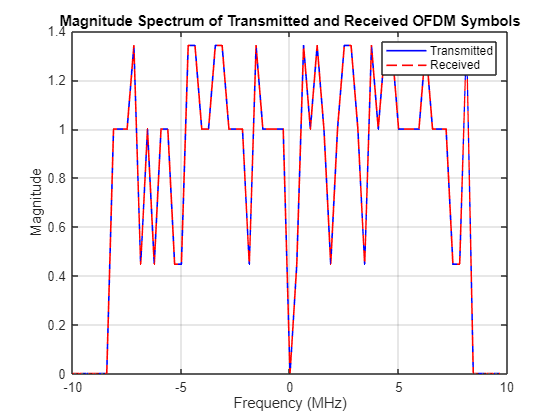

C = fftshift(fft(c));
f_axis = (-FFT_size/2 : FFT_size/2-1) * sc_space / 1e6;   % MHz

figure;
plot(f_axis, abs(Xc), 'b', 'LineWidth', 1.2); 
hold on;
plot(f_axis, abs(C),  'r--', 'LineWidth', 1.2, 'MarkerSize', 4);
grid on;

xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Transmitted and Received OFDM Symbols');
legend('Transmitted','Received');

### (8)

function x_cp = gen_ofdm_symbol()
    FFT_size = 64;
    cp_size = 16;
    %% 802.11a/g subcarrier allocation
    active_sc  = [-26:-1 1:26];           % 52 active subcarriers
    pilot_sc = [-21 -7 7 21];           % 4 pilot tones
    data_sc  = setdiff(active_sc, pilot_sc); % 48 data tones

    %% 1. Generate pilot symbols (BPSK)
    pilot_bits = randi([0 1], length(pilot_sc), 1);
    pilot_sym = 2*pilot_bits - 1;       
    
    %% 2. Generate data symbols (16-QAM)
    % 16-QAM => 4 bits per symbol
    data_bits = randi([0 1], length(data_sc)*4, 1);
    data_sym = qammod(data_bits, 16, 'InputType', 'bit', 'UnitAveragePower', true);
    
    %% 3. Generate OFDM symbols
    Xc = zeros(FFT_size,1);
    sc2idx = @(k) k + FFT_size/2 + 1; % map the sc idx to 1-64
    
    % map pilot&data
    for i = 1:length(pilot_sc)
        Xc(sc2idx(pilot_sc(i))) = pilot_sym(i);
    end
    for i = 1:length(data_sc)
        Xc(sc2idx(data_sc(i))) = data_sym(i);
    end
    
    % ifft and adding cp
    a = ifft(ifftshift(Xc));
    x_cp = [a(end-cp_size+1:end); a];
end

num_symbols = 1000;
x_cp_1000 = zeros(80, num_symbols);

for n = 1:num_symbols
    x_cp_1000(:, n) = gen_ofdm_symbol();
end

power_samples = abs(x_cp_1000).^2; 

peak_power = max(power_samples(:))

peak_power = 0.1439

avg_power = mean(power_samples(:))

avg_power = 0.0127

PAPR = peak_power / avg_power

PAPR = 11.3483

PAPR_dB    = 10*log10(PAPR);
fprintf('PAPR = %.4f dB\n', PAPR_dB);

PAPR = 10.5493 dB


### (9)

**1. It can cause clipping in the D/A converter.**

Since an OFDM signal is the sum of many subcarriers, its instantaneous amplitude can become very large at some time instants. If the peak exceeds the dynamic range of the D/A converter, clipping will happen and distort the signal. 

**2. It can make the transmitter power amplifier saturate.**

When the signal peak is too high, the power amplifier may no longer operate in its linear region and enter saturation. This causes nonlinear distortion and degrades the transmission quality.

### (10)


$$\textrm{To}\;\textrm{let}\;\textrm{SNR}=15\textrm{dB}\;\Longrightarrow$$
 
$$10*\log_{10} \left(\frac{P_{\textrm{sig}} }{P_{\textrm{noise}} }\right)=15\;$$

$$\Longrightarrow$$
 
$$P_{\textrm{noise}} =\frac{P_{\textrm{sig}} }{{10}^{1\ldotp 5} }\;$$



$$\textrm{For}\;\textrm{complex}\;\textrm{Gaussian}\;\textrm{noise}\sim \textrm{CN}\left(0,\sigma^2 \right),\;\;$$

$$P_{\textrm{noise}} =\frac{P_{\textrm{sig}} }{{10}^{1\ldotp 5} }=\sigma^2$$


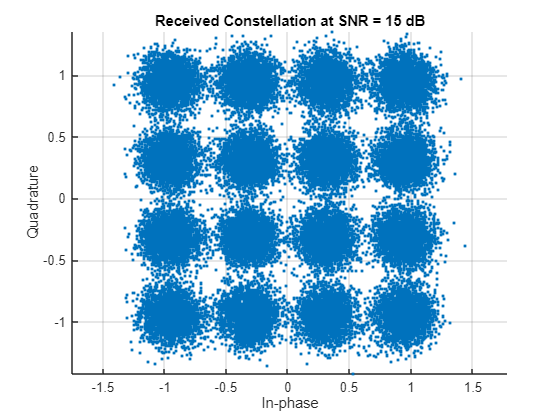

rx = [];

for n = 1:size(x_cp_1000,2)
    x_cp = x_cp_1000(:,n);

    P_sig = mean(abs(x_cp).^2);
    P_noise = P_sig / (10^(1.5));
    sigma_square = P_noise;
    % add complex Gaussian noise
    noise = sqrt(sigma_square/2) * (randn(size(x_cp)) + 1j*randn(size(x_cp)));
    y_cp = x_cp + noise;

    % remove CP
    y = y_cp(17:end);
    y_all(:,n) = y;   
    Y = fftshift(fft(y));

    % collect data tones only
    rx_data = Y(sc2idx(data_sc));
    rx = [rx; rx_data];
end

figure;
scatter(real(rx), imag(rx), '.');
grid on;
axis equal;
xlabel('In-phase');
ylabel('Quadrature');
title('Received Constellation at SNR = 15 dB');

### (11)

x_1000 = x_cp_1000(cp_size+1:end, :);

P_Sig = mean(abs(x_1000(:)).^2);
P_n = mean(abs(y_all(:) - x_1000(:)).^2);
SNR = 10*log10(P_Sig/P_n);
fprintf('Estimated SNR = %.4f dB\n', SNR);

Estimated SNR = 15.0388 dB


### (12)

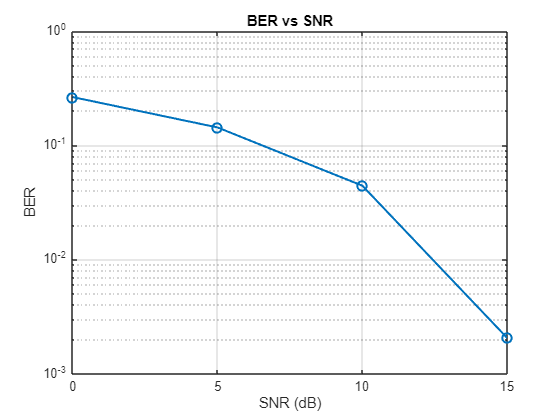

SNR_dB_list = [0 5 10 15];
BER = zeros(size(SNR_dB_list));


X_tx = fftshift(fft(x_1000, FFT_size, 1), 1);   
tx_data = X_tx(data_idx, :);                    
tx_bits = qamdemod(tx_data(:), 16, 'OutputType', 'bit', 'UnitAveragePower', true);

for s = 1:length(SNR_dB_list)
    SNR_dB = SNR_dB_list(s);
    sigma_square = P_Sig / (10^(SNR_dB/10));

    % complex Gaussian noise
    noise = sqrt(sigma_square/2) * (randn(size(x_1000)) + 1j*randn(size(x_1000)));
    y = x_1000 + noise;
    
    Y = fftshift(fft(y, FFT_size, 1), 1);   
    rx_data = Y(data_idx, :);               
    rx_bits = qamdemod(rx_data(:), 16, 'OutputType', 'bit', 'UnitAveragePower', true);
    BER(s) = mean(rx_bits ~= tx_bits);
end

figure;
plot(SNR_dB_list, BER, 'o-', 'LineWidth', 1.5, 'MarkerSize', 7);
grid on;
xlabel('SNR (dB)');
ylabel('BER');
title('BER vs SNR');ax = gca;
ax.YScale = 'log';
ax.YLim = [1e-3 1e0];
ax.YTick = [1e-3 1e-2 1e-1 1e0];

It can be observed that the BER monotonically decreases as SNR increases. At low SNR, noise has a stronger impact on the received signal, leading to more bit errors. As SNR becomes higher, the received symbols are less corrupted by noise, so the BER is reduced. Overall, the figure demonstrates the expected inverse relationship between BER and SNR. Another thing that note worthy is that the decline of BER is more and more steep as SNR increase.

## [Part 2]

%clearvars; clc;
FFT_size = 64;
cp_size = 16;
fs = 20e6;
sc_space = fs/FFT_size;
%% 802.11a/g subcarrier allocation
active_sc  = [-26:-1 1:26];           % 52 active subcarriers
pilot_sc = [-21 -7 7 21];           % 4 pilot tones
data_sc  = setdiff(active_sc, pilot_sc); % 48 data tones

### (1)

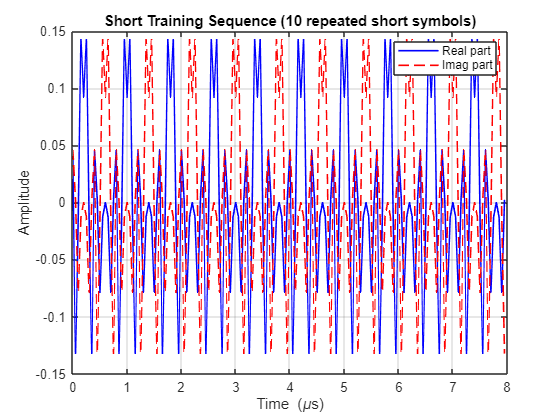

% STS frequency-domain pattern (802.11a/g short training symbol)
STS = zeros(FFT_size,1);
sc2idx = @(k) k + FFT_size/2 + 1;

sts_sc = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
sts_val = sqrt(13/6) * [1+1j, -1-1j,  1+1j, -1-1j, -1-1j,  1+1j, -1-1j, -1-1j, 1+1j,  1+1j,  1+1j,  1+1j];
STS(sc2idx(sts_sc)) = sts_val;

sts = ifft(ifftshift(STS));
STS = repmat(sts(1:16), 10, 1);
t = (0:length(STS)-1) / fs * 1e6;

figure;
plot(t, real(STS), 'b', 'LineWidth', 1.2); 
hold on;
plot(t, imag(STS), 'r--', 'LineWidth', 1.2);
grid on;
xlabel('Time (\mus)');
ylabel('Amplitude');
title('Short Training Sequence (10 repeated short symbols)');
legend('Real part','Imag part');

### (2)

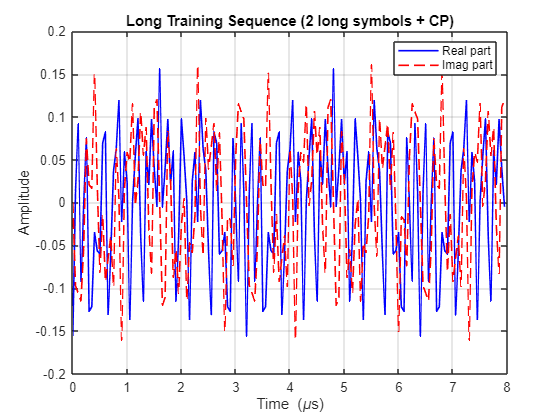

% LTS frequency-domain sequence
lts_seq = [1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1,  1,  1, ...
    -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1,  0,  1, -1, -1, ...
     1,  1, -1,  1, -1,  1, -1, -1, -1, -1, -1,  1,  1, -1, -1, ...
     1, -1,  1, -1,  1,  1,  1,  1];

lts_sc = -26:26;   

LTS = zeros(FFT_size,1);
LTS(sc2idx(lts_sc)) = lts_seq;

% one 64-sample long training symbol
lts = ifft(ifftshift(LTS));

% cyclic prefix for LTS = last 32 samples of one LTS
lts_cp = lts(end-32+1:end);

% full LTS = CP + two repeated long symbols
LTS = [lts_cp; lts; lts];
t = (0:length(LTS)-1) / fs * 1e6;

% plot
figure;
plot(t, real(LTS), 'b', 'LineWidth', 1.2); hold on;
plot(t, imag(LTS), 'r--', 'LineWidth', 1.2);
grid on;
xlabel('Time (\mus)');
ylabel('Amplitude');
title('Long Training Sequence (2 long symbols + CP)');
legend('Real part','Imag part');

### (3)

% generate 5 OFDM symbols
data = [];
for k = 1:5
    data = [data; gen_ofdm_symbol()];
end

% normalize each part to have consistent average power
STS_n = STS / sqrt(mean(abs(STS).^2));
LTS_n = LTS / sqrt(mean(abs(LTS).^2));
data_n = data / sqrt(mean(abs(data).^2));
%%% VERIFY
P_STS  = mean(abs(STS_n).^2)

P_STS = 1

P_LTS  = mean(abs(LTS_n).^2)

P_LTS = 1.0000

P_data = mean(abs(data_n).^2)

P_data = 1

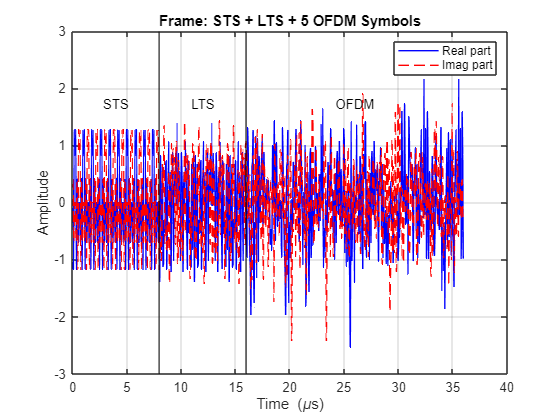

frame = [STS_n; LTS_n; data_n];
t = (0:length(frame)-1) / fs * 1e6;

idx1 = 1;
idx2 = length(STS_n);
idx3 = length(STS_n) + length(LTS_n);
idx4 = length(STS_n) + length(LTS_n) + length(data_n);

figure;
plot(t, real(frame), 'b', 'LineWidth', 1.1); 
hold on;
plot(t, imag(frame), 'r--', 'LineWidth', 1.1);
grid on;

xline(t(idx2), 'k', 'LineWidth', 1.2);
xline(t(idx3), 'k', 'LineWidth', 1.2);
text(t(round(idx2/2)), 0.8*max(real(frame)), 'STS', 'HorizontalAlignment', 'center');
text(t(round((idx2+idx3)/2)), 0.8*max(real(frame)), 'LTS', 'HorizontalAlignment', 'center');
text(t(round((idx3+idx4)/2)), 0.8*max(real(frame)), 'OFDM', 'HorizontalAlignment', 'center');

xlabel('Time (\mus)');
ylabel('Amplitude');
title('Frame: STS + LTS + 5 OFDM Symbols');
legend('Real part','Imag part');

### (4)

% one sts
sts_short = STS(1:16);

% matched filter coefficients
h_sts = conj(flipud(sts_short));

% matched filter output
mf_sts = conv(frame, h_sts);

% find peak
[~, peak_idx] = max(abs(mf_sts));

1. I use one short training symbol as the reference template because the STS is made of 10 repeated short symbols. 

2. I build a matched filter by taking the time-reversed and conjugated version of this short symbol.


$$h\left\lbrack n\right\rbrack =s^* \left\lbrack L-1-n\right\rbrack \;,\textrm{here}\;L\;\textrm{is}\;\textrm{the}\;\textrm{length}\;\textrm{of}\;\textrm{the}\;\textrm{known}\;\textrm{reference}\;\textrm{symbol}$$
 

3. Do convolution of the received signal with this matched filter and look for the peak in the output. When the received signal matches the STS, the matched filter output becomes large, so the peak location can be used to estimate the beginning of the frame. The procedure is showed below.

4. Since the time complexity of doing convolution is $O\left(\textrm{NL}\right),N\;\textrm{is}\;\textrm{the}\;\textrm{received}\;\textrm{signal}\;\textrm{length}\;\textrm{and}\;L\;\textrm{is}\;\textrm{the}\;\textrm{matched}\;\textrm{filter}\;\textrm{length}\ldotp$ Use one sts as reference symbol insteading of using the whole ten copies can save much running time by a factor of 10. 

% estimated start of frame
est_start = peak_idx - length(sts_short) + 1;
fprintf('Estimated frame start index = %d\n', est_start);

Estimated frame start index = 1


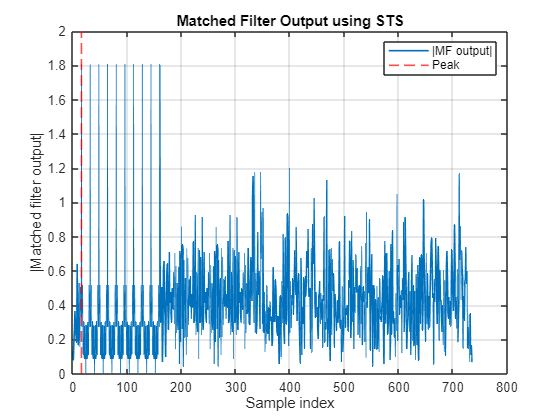

% plot matched filter result
n = 1:length(mf_sts);
figure;
plot(n, abs(mf_sts), 'LineWidth', 1.2); hold on;
xline(peak_idx, 'r--', 'LineWidth', 1.2);
grid on;
xlabel('Sample index');
ylabel('|Matched filter output|');
title('Matched Filter Output using STS');
legend('|MF output|','Peak');

### (5)

padded_sig = [zeros(30,1); frame; zeros(30,1)];

mf_out = conv(padded_sig, h_sts);
[~, peak_idx] = max(abs(mf_out));
est_start = peak_idx - length(sts_short) + 1;
true_start = 30 + 1;
fprintf('True frame start index      = %d\n', true_start);

True frame start index      = 31


fprintf('Estimated frame start index = %d\n', est_start);

Estimated frame start index = 31


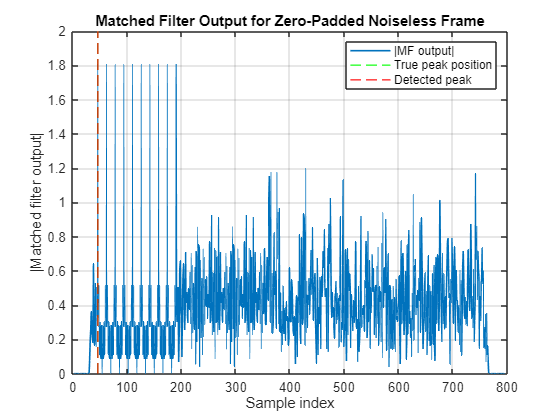

n = 1:length(mf_out);

figure;
plot(n, abs(mf_out), 'LineWidth', 1.2); 
hold on;
xline(true_start + length(sts_short) - 1, 'g--', 'LineWidth', 1.2);
xline(peak_idx, 'r--', 'LineWidth', 1.2);
grid on;

xlabel('Sample index');
ylabel('|Matched filter output|');
title('Matched Filter Output for Zero-Padded Noiseless Frame');
legend('|MF output|','True peak position','Detected peak');

The figure shows that in the STS part of the OFDM signal, the matched filter results in 10 periodic peaks, corresponding to ten copies of 16 samples single sts component. Moreover, the beginning of the frame is simply gained from the position of the first peak, and the result shows that the estimated index is same as the true index, which is number of padding zeros 30 + 1(the start of STS) = 31.

### (6)

len_STS = 160;
len_LTS = 160;
len_sym = 80;   
num_data_sym = 5;

data_start = est_start + len_STS + len_LTS;
rx_data_all = zeros(len_sym, num_data_sym);

for k = 1:num_data_sym
    sym_start = data_start + (k-1)*len_sym;
    sym_end   = sym_start + len_sym - 1;

    xk_cp = padded_sig(sym_start:sym_end);
    rx_data_all(:,k) = xk_cp;
end
rx_bits = qamdemod(rx_data_all(:), 16, 'OutputType', 'bit', 'UnitAveragePower', true);
tx_bits = qamdemod(data_n, 16, 'OutputType', 'bit', 'UnitAveragePower', true);
num_error = sum(rx_bits ~= tx_bits(:));
fprintf('Number of bit errors = %d\n', num_error);

Number of bit errors = 0


### (7)

% SNR = 0 means that P_noise = P_sig
P_sig = mean(abs(padded_sig).^2);
P_noise = P_sig;
sigma_square = P_noise;

noise = sqrt(sigma_square/2) * (randn(size(padded_sig)) + 1j*randn(size(padded_sig)));

rx_sig_noisy = padded_sig + noise;
mf_out_noisy = conv(rx_sig_noisy, h_sts);
[~, peak_idx] = max(abs(mf_out_noisy));
est_start = peak_idx - length(sts_short) + 1;
true_start = 30 + 1;
fprintf('True frame start index      = %d\n', true_start);

True frame start index      = 31


fprintf('Estimated frame start index = %d\n', est_start);

Estimated frame start index = 47


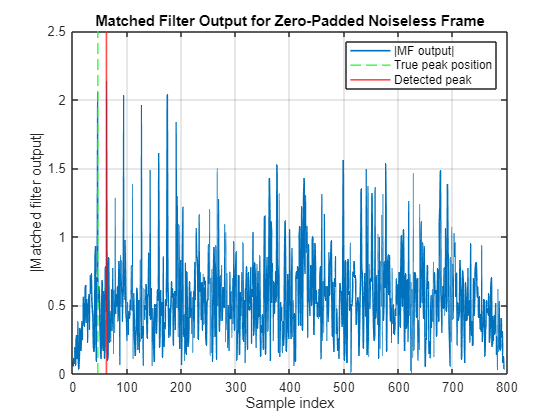

n = 1:length(mf_out_noisy);
figure;
plot(n, abs(mf_out_noisy), 'LineWidth', 1.2); 
hold on;
xline(true_start + length(sts_short) - 1, 'g--', 'LineWidth', 1.2);
xline(peak_idx, 'r', 'LineWidth', 1.2);
grid on;

xlabel('Sample index');
ylabel('|Matched filter output|');
title('Matched Filter Output for Zero-Padded Noiseless Frame');
legend('|MF output|','True peak position','Detected peak');

Due to the added noise, the ten peaks in the STS region are no longer equal in magnitude, and the peaks in other regions also become larger and may get close to the target peaks. If the first peak in the STS region is no longer the largest among ten, or a peak in another region becomes larger than a peak in the STS region, then the algorithm result will be incorrect. (In 0 SNR case here, the effect of noise is SO significant)

To solve of the problem that the first peak is not the highest one among ten peaks in STS, a simple propose is to find the top-10 peaks of the matched filter result, and set the estimated index as the frontmost peak index. BUT the time complexity of finding them is $O\left(N\right)$, and the "N" here is the whole padding signal, which is in fact really large, which conflicts with the original idea of reducing the running time. 

What makes things worse is that the revised algo can't slove the problem of the magnitude in other regions exceeds those in STS region(This problem also exists in using the whole STS as the reference signal in mf). I think increase the SNR, and accept the trade-off of sacrificing some accuracy in order to reduce the running time and computational resources seems to be a reasonable concept.

### (8)

Because the STS-based matched filter produces repeated peaks due to the repeated short symbols, the detection result can be more easily affected by noise. Therefore, in this part, I would like to try** using the two complete LTS symbols as the target template** in the matched filter instead of only one segment. The matched filter implementation is same as in (4).

### (9)

lts_template = LTS(33:end);           
h_lts = conj(flipud(lts_template));      

mf_lts = conv(rx_sig_noisy, h_lts);
[~, peak_idx] = max(abs(mf_lts));
est_lts_start = peak_idx - length(lts_template) + 1;
true_lts_start = 30 + 160 + 32 + 1; % pad + STS + LTS_CP

fprintf('True LTS template start index      = %d\n', true_lts_start);

True LTS template start index      = 223


fprintf('Estimated LTS template start index = %d\n', est_lts_start);

Estimated LTS template start index = 223


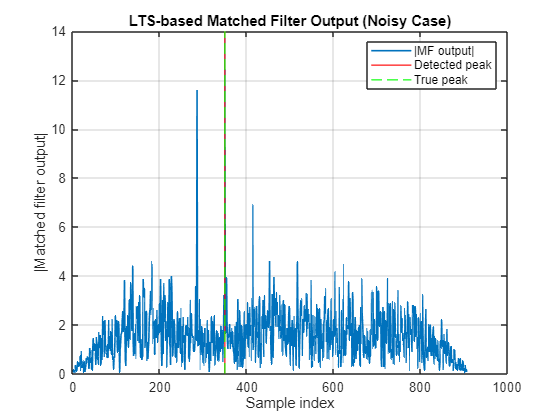

n = 1:length(mf_lts);

figure;
plot(n, abs(mf_lts), 'LineWidth', 1.2); 
hold on;
xline(peak_idx, 'r', 'LineWidth', 1.2);
xline(true_lts_start + length(lts_template) - 1, 'g--', 'LineWidth', 1.2);
grid on;
xlabel('Sample index');
ylabel('|Matched filter output|');
title('LTS-based Matched Filter Output (Noisy Case)');
legend('|MF output|', 'Detected peak', 'True peak');

From the figure we can see that besides the largest peak, there are still other obvious peaks in the matched filter output, which are caused by the added noise. Though above statements implies that the problem that noise may create a wrong peak is not completely eliminated. However, in my simulations, the detected peak is still correct in many repeated runs.

### (10)

The result in Q(7) is less accurate than the LTS-based method in Q(9), the main reason is because the repeated short symbols produce repeated peaks, and noise may change their relative heights. 

Although the problem that the noise may cause a peak exceeds the targeted one exists, the result in Q(9) shows that in the SNR = 0 dB case, the effect of noise making a non-targeted region exceed the targeted peak is much less significant. Moreover, it is known that the STS and LTS have the same average power from the power normalization so choosing the whole STS as reference of mf will get the same result as in Q(9) (But the length of LTS is shorter).

The pros of the proposition in Q(4) is that the mf length is only 16, which saves running time and computational resources. However, it is a trade-off of estimation accuracy, which is the cons here.

The pros and cons in the design of (8) are the inverse of (4), the matched filter uses two complete LTS symbols as the template, whose total length is 128, improving accuracy at the cost of efficiency. 

### (11)

The filter design in (8) uses a filter tap of 128, which is more than 100. A more efficient method can use the same idea in (4), using one single LTS symbol rather than two. 

I think the descriptions before (In Q(4、7、9、10)) is already complete enough, including the algorithm details, implementation and the trade-off. So I will not repeat them here.

### (12)

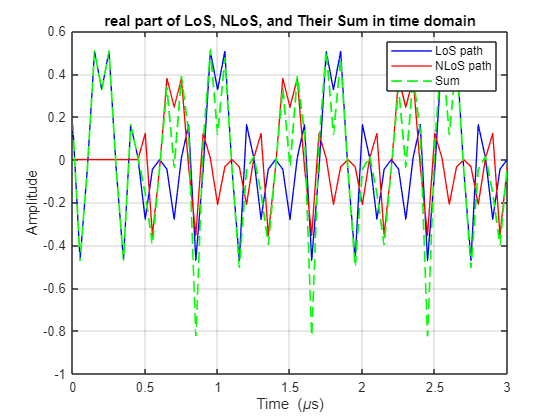

% channel parameters
alpha_LoS = 0.4;
alpha_NLoS = 0.3;
tau_LoS_us  = 0;
tau_NLoS_us = 0.5;  

delay_LoS  = round(tau_LoS_us  * 1e-6 * fs);
delay_NLoS = round(tau_NLoS_us * 1e-6 * fs);
rx_len = length(frame) + delay_NLoS;

frame_LoS  = zeros(rx_len,1);
frame_NLoS = zeros(rx_len,1);

frame_LoS(1+delay_LoS : delay_LoS+length(frame)) = alpha_LoS * frame;
frame_NLoS(1+delay_NLoS : delay_NLoS+length(frame)) = alpha_NLoS * frame;
frame_rx = frame_LoS + frame_NLoS;
t_rx = (0:length(frame_rx)-1) / fs * 1e6;   % us

figure;
plot(t_rx, real(frame_LoS),  'b',  'LineWidth', 1.0); hold on;
plot(t_rx, real(frame_NLoS), 'r','LineWidth', 1.0);
plot(t_rx, real(frame_rx),   'g--',  'LineWidth', 1.3);
grid on;
xlabel('Time (\mus)');
ylabel('Amplitude');
title('real part of LoS, NLoS, and Their Sum in time domain');
legend('LoS path', 'NLoS path', 'Sum');
xlim([0 3]);

### (13)

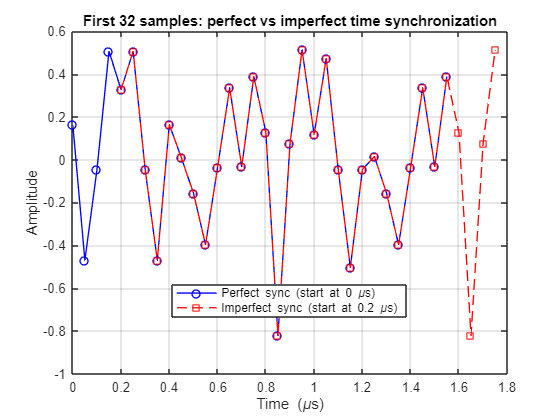

t_start = 0.2;
delay_samps = round(t_start * 1e-6 * fs);   % samples

% perfect synchronization
rx_perfect = frame_rx;

% imperfect synchronization: miss the first few samples
rx_imperfect = frame_rx(1 + delay_samps : end);

N_show = 32;
n_perfect = 0:N_show-1;
n_imperfect = delay_samps:(delay_samps + N_show - 1);

t_perfect = n_perfect / fs * 1e6;      % us
t_imperfect = n_imperfect / fs * 1e6;  % us

figure;
plot(t_perfect, real(rx_perfect(1:N_show)), 'bo-', 'LineWidth', 1.0);
hold on;
plot(t_imperfect, real(rx_imperfect(1:N_show)), 'rs--', 'LineWidth', 1.0);
grid on;
xlabel('Time (\mus)');
ylabel('Amplitude');
title('First 32 samples: perfect vs imperfect time synchronization');
legend('Perfect sync (start at 0 \mus)', 'Imperfect sync (start at 0.2 \mus)', 'Location', 'best');

The figure compares the first 32 samples of the perfectly synchronized received signal and the imperfectly synchronized received signal. The imperfect case starts sampling at 0.2μs, so its waveform has the same overall shape as the perfectly synchronized case but is shifted to the right with time offset 0.2μs, which can confirm the imperfect synchronization is correctly implemented.

### (14)

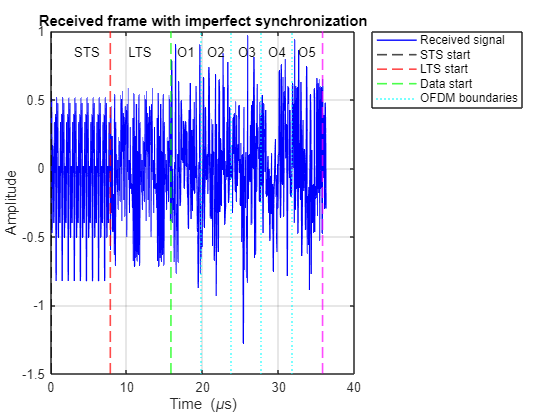

%% compute the sum of LTS template go through two channel as the reference of mf
lts_len = length(lts_template) + delay_NLoS;

lts_template_LoS  = zeros(lts_len,1);
lts_template_NLoS = zeros(lts_len,1);

lts_template_LoS(1+delay_LoS : delay_LoS+length(lts_template)) = alpha_LoS * lts_template;
lts_template_NLoS(1+delay_NLoS : delay_NLoS+length(lts_template)) = alpha_NLoS * lts_template;
lts_template_rx = lts_template_LoS + lts_template_NLoS;

%% mf design and implementation
h_lts = conj(flipud(lts_template_rx)); 
mf_imperfect = conv(rx_imperfect, h_lts);
[~, peak_idx] = max(abs(mf_imperfect));
est_lts_start = peak_idx - lts_len + 1; 
len_STS_impe = len_STS - 4; % 4 samples are killed since imperfect time sync.

sts_start = est_lts_start - len_STS_impe - 32; % 32 here is the CP of LTS
sts_end   = est_lts_start - 1;

lts_start = est_lts_start - 32;
lts_end   = lts_start + len_LTS - 1;

data_start = lts_end + 1;
data_end   = data_start + num_data_sym * len_sym - 1;

ofdm1_start = data_start;
ofdm1_end   = ofdm1_start + len_sym - 1;

ofdm2_start = ofdm1_end + 1;
ofdm2_end   = ofdm2_start + len_sym - 1;

ofdm3_start = ofdm2_end + 1;
ofdm3_end   = ofdm3_start + len_sym - 1;

ofdm4_start = ofdm3_end + 1;
ofdm4_end   = ofdm4_start + len_sym - 1;

ofdm5_start = ofdm4_end + 1;
ofdm5_end   = ofdm5_start + len_sym - 1;

rx_sts = rx_imperfect(sts_start:sts_end);
rx_lts = rx_imperfect(lts_start:lts_end);
rx_ofdm1 = rx_imperfect(ofdm1_start:ofdm1_end);
rx_ofdm2 = rx_imperfect(ofdm2_start:ofdm2_end);
rx_ofdm3 = rx_imperfect(ofdm3_start:ofdm3_end);
rx_ofdm4 = rx_imperfect(ofdm4_start:ofdm4_end);
rx_ofdm5 = rx_imperfect(ofdm5_start:ofdm5_end);
t_rx = (0:length(rx_imperfect)-1) / fs * 1e6; 

figure;
plot(t_rx, real(rx_imperfect), 'b', 'LineWidth', 1.0); 
hold on;
grid on;
xlabel('Time (\mus)');
ylabel('Amplitude');
title('Received frame with imperfect synchronization');

xline((sts_start-1)/fs*1e6,  'k--', 'LineWidth', 1.2);
xline((lts_start-1)/fs*1e6,  'r--', 'LineWidth', 1.2);
xline((data_start-1)/fs*1e6, 'g--', 'LineWidth', 1.2);

xline((ofdm1_end)/fs*1e6, 'c:');
xline((ofdm2_end)/fs*1e6, 'c:');
xline((ofdm3_end)/fs*1e6, 'c:');
xline((ofdm4_end)/fs*1e6, 'c:');
xline((ofdm5_end)/fs*1e6, 'm--', 'LineWidth', 1.2);

yl = ylim;
text(((sts_start+sts_end)/2-1)/fs*1e6, 0.85*yl(2), 'STS', 'HorizontalAlignment', 'center');
text(((lts_start+lts_end)/2-1)/fs*1e6, 0.85*yl(2), 'LTS', 'HorizontalAlignment', 'center');
text(((ofdm1_start+ofdm1_end)/2-1)/fs*1e6, 0.85*yl(2), 'O1', 'HorizontalAlignment', 'center');
text(((ofdm2_start+ofdm2_end)/2-1)/fs*1e6, 0.85*yl(2), 'O2', 'HorizontalAlignment', 'center');
text(((ofdm3_start+ofdm3_end)/2-1)/fs*1e6, 0.85*yl(2), 'O3', 'HorizontalAlignment', 'center');
text(((ofdm4_start+ofdm4_end)/2-1)/fs*1e6, 0.85*yl(2), 'O4', 'HorizontalAlignment', 'center');
text(((ofdm5_start+ofdm5_end)/2-1)/fs*1e6, 0.85*yl(2), 'O5', 'HorizontalAlignment', 'center');

legend('Received signal', 'STS start', 'LTS start', 'Data start', 'OFDM boundaries', 'Location', 'northeastoutside');

### (15)

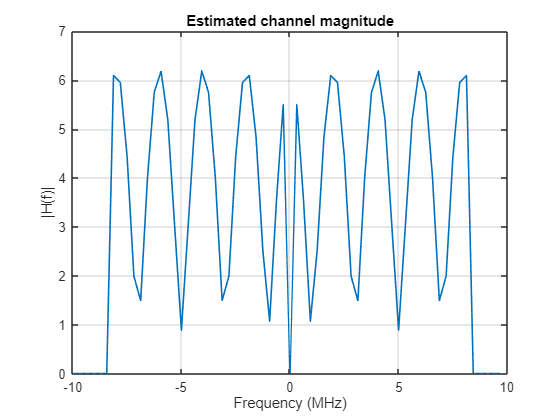

rx_lts_1 = rx_lts(33:96);
rx_lts_2 = rx_lts(97:160);

Rx_LTS_1 = fftshift(fft(rx_lts_1));
Rx_LTS_2 = fftshift(fft(rx_lts_2));

% average the two LTSs
Rx_LTS_avg = (Rx_LTS_1 + Rx_LTS_2) / 2;

Tx_LTS = zeros(FFT_size,1);
Tx_LTS(sc2idx(lts_sc)) = lts_seq;

% LS channel estimation
H_est = Rx_LTS_avg ./ Tx_LTS;

%% avoid divide-by-zero / null subcarriers
null_idx = (abs(Tx_LTS) < 1e-12);
H_est(null_idx) = 0;

f_axis = (-FFT_size/2:FFT_size/2-1) * (fs/FFT_size) / 1e6;

figure;
plot(f_axis, abs(H_est), 'LineWidth', 1.2);
grid on;
xlabel('Frequency (MHz)');
ylabel('|H(f)|');
title('Estimated channel magnitude');

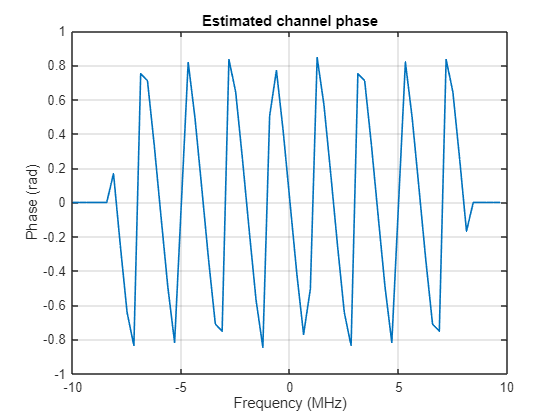

figure;
plot(f_axis, angle(H_est), 'LineWidth', 1.2);
grid on;
xlabel('Frequency (MHz)');
ylabel('Phase (rad)');
title('Estimated channel phase');

### (16)

The estimated channel is frequency-selective, since the channel magnitude is not constant across subcarriers. Different frequencies experience different channel gains, so the channel response cannot be regarded as frequency-flat.

The magnitude response is also approximately even-symmetric around the center frequency. This is because the two-path channel creates a structured interference pattern in frequency, and the delayed path affects positive and negative frequency components in a similar way.

In addition, the magnitude shows a clear periodic ripple pattern with repeated peaks and dips. This is caused by the superposition of the LoS path and the delayed NLoS path. As frequency changes, the phase difference between the two paths changes continuously, so the two paths alternately combine constructively and destructively.

### (17)

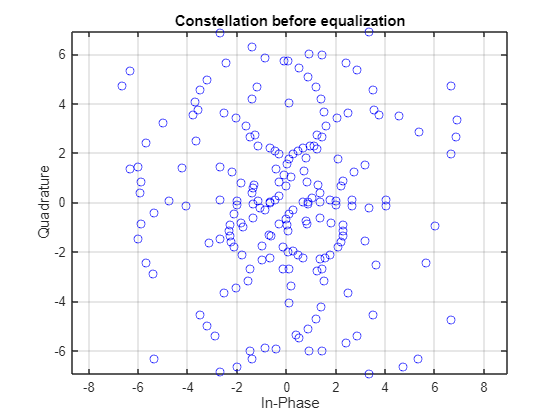

rx_ofdm_all = {rx_ofdm1, rx_ofdm2, rx_ofdm3, rx_ofdm4, rx_ofdm5};

rx_data_all = [];
eq_data_all = [];

data_idx = sc2idx(data_sc);
for k = 1:num_data_sym
    rx_ofdm = rx_ofdm_all{k};
    
    % remove CP
    rx_ofdm_no_cp = rx_ofdm(cp_size+1 : cp_size + FFT_size);
    
    % FFT
    rx_ofdm_fd = fftshift(fft(rx_ofdm_no_cp));
    
    % equalization
    eq_ofdm_fd = rx_ofdm_fd ./ H_est;
    
    % collect data tones
    rx_data_all = [rx_data_all; rx_ofdm_fd(data_idx)];
    eq_data_all = [eq_data_all; eq_ofdm_fd(data_idx)];
end

figure;
plot(real(rx_data_all), imag(rx_data_all), 'bo');
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('Constellation before equalization');
axis equal;

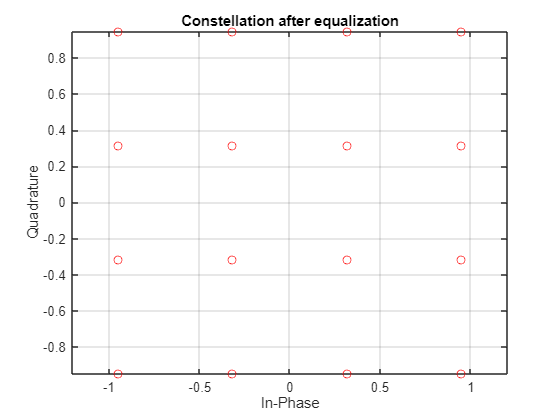

figure;
plot(real(eq_data_all), imag(eq_data_all), 'ro');
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('Constellation after equalization');
axis equal;

### (18)

rx_bits = qamdemod(eq_data_all, 16, 'gray', 'UnitAveragePower', true, 'OutputType', 'bit');
rx_bits = rx_bits.';
rx_bits = rx_bits(:);

tx_data_all = [];

for k = 1:num_data_sym
    tx_ofdm = data((k-1)*len_sym + 1 : k*len_sym);  
    tx_ofdm_no_cp = tx_ofdm(cp_size+1 : cp_size + FFT_size); 
    tx_ofdm_fd = fftshift(fft(tx_ofdm_no_cp)); 
    tx_data_all = [tx_data_all; tx_ofdm_fd(data_idx)];
end

tx_bits = qamdemod(tx_data_all, 16, 'gray','UnitAveragePower', true, 'OutputType', 'bit');
tx_bits = tx_bits.';
tx_bits = tx_bits(:);

num_bit_error = sum(rx_bits ~= tx_bits);
fprintf('Number of bit errors = %d\n', num_bit_error);

Number of bit errors = 0
